
% opgave 1.5 giver vidst ikke de rigtige tal REVIDER!
clear

bi = [1,0,1]

bi =      1     0     1


ai = [1,5,6]

ai =      1     5     6



[ro,po,ko] = residuez(bi,ai)

ro =     3.3333
   -2.5000


po =    -3.0000
   -2.0000


ko = 0.1667

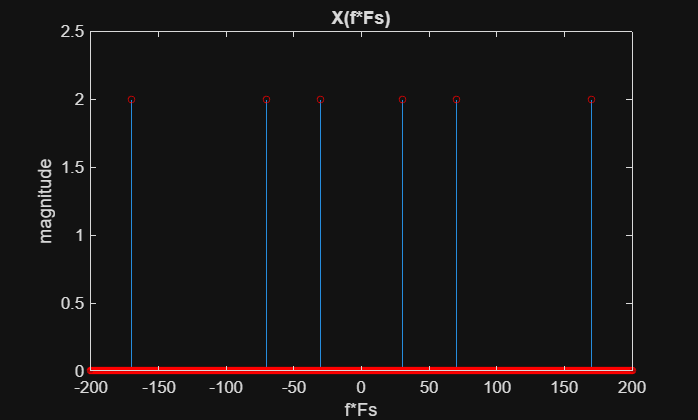

%kode til opgave 2.1

F1 = 70; 
F2 = 100; 
A1 = 4; 
A2 = 2; 
Fs = 5000; 
N = 1e7;
Ts = 1/Fs;


%Xat = A1*cos(2*pi*F1*t)*(1+A2*cos(2*pi*F2*t))

% vi skal sample på signalet og derfor laver vi det digitale signal: 
% først skal vi lave en sample vektor "n"
f = (-N/2:N/2-1)/N;

fHz = f*Fs;
n = [0:1:N-1];

xn = A1*cos(2*pi*F1*n*Ts).*(1+A2*cos(2*pi*F2*n*Ts));

Xz = fftshift(fft(xn)); 

stem(fHz,abs(Xz)/N,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
title("X(f*Fs)")
xlim([-200,200]);
ylim([0,2.5]);
xlabel("f*Fs");
ylabel("magnitude");


Fs = 5000; %samplingfrekvens 
%koefficenterne på filteret
b = [0.915767, -2.747302, 2.747302, -0.915767];
a = [1 ,-2.824127, 2.663381, -0.838630];

[H_dig, digfreq] = freqz(b,a,1024,Fs); %indskriver værdier i Hz
%vi plotter som funktion af f*Fs
plot(digfreq,abs(H_dig))
title("H(f*Fs)")
xlim([0,200]);
ylim([0,1.2]);
xlabel("f*Fs");
ylabel("magnitude");
hold on 

%denne kodesnip nedenfor er til at indexere i de valgte punkter
[~, idx30] = min(abs(digfreq - 30));
[~, idx70] = min(abs(digfreq - 70));
[~, idx170] = min(abs(digfreq - 170));
% Hent værdierne på frekvensresponsen
y30 = abs(H_dig(idx30))

y30 = 0.0731

y70 = abs(H_dig(idx70))

y70 = 0.7188

y170 = abs(H_dig(idx170))

y170 = 0.9977

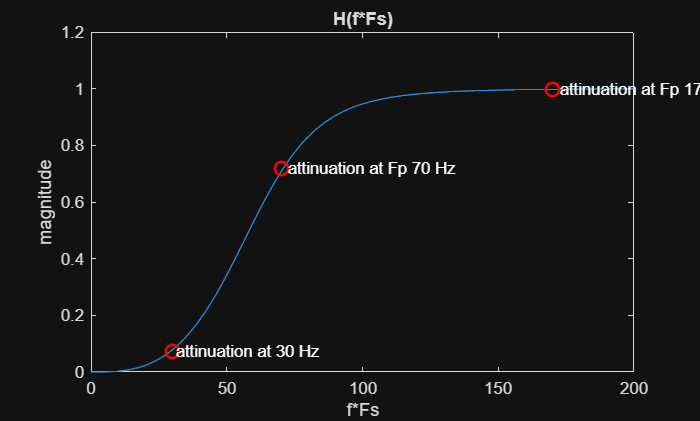


% denne del kan også udelades hvis der bare skal findes værdier
% Plot punkterne
plot(30, y30, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(70, y70, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(170, y170, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)

text(digfreq(idx30), y30, ' attinuation at 30 Hz', 'Color','white', 'FontSize',10);
text(digfreq(idx70), y70, ' attinuation at Fp 70 Hz', 'Color','white', 'FontSize',10);
text(digfreq(idx170), y170, ' attinuation at Fp 170', 'Color','white', 'FontSize',10);
hold off 
hold off

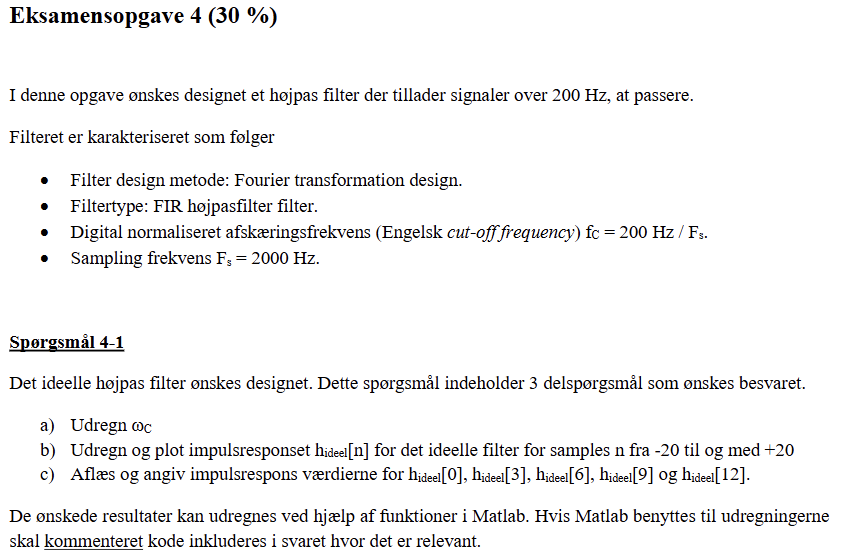

clear
Fs = 2000; %sampling frekvens
Ts = 1/Fs; % sampling periode 
fc = 200/Fs; % norm cutoff
wc = fc*2*pi %norm angulær cutoff

wc = 0.6283

%n vektor til at iterere 
n = [-20:1:20]; 

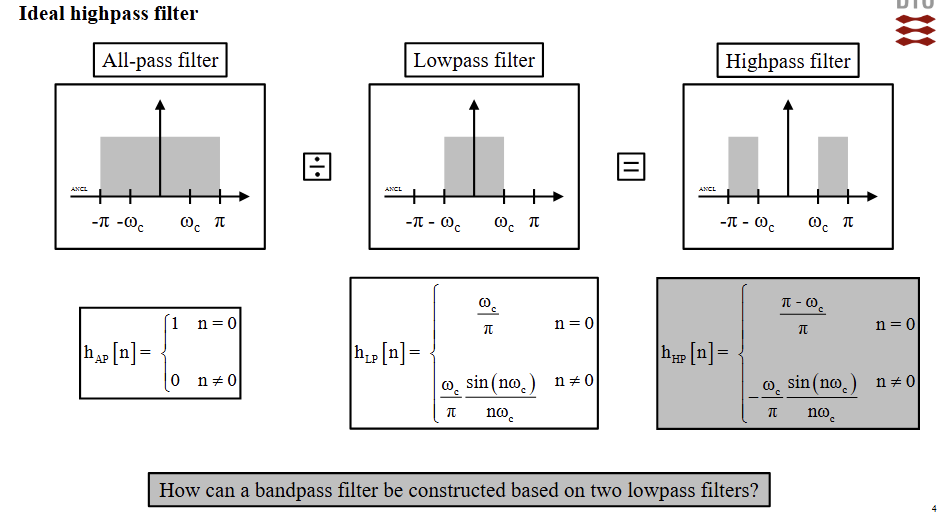

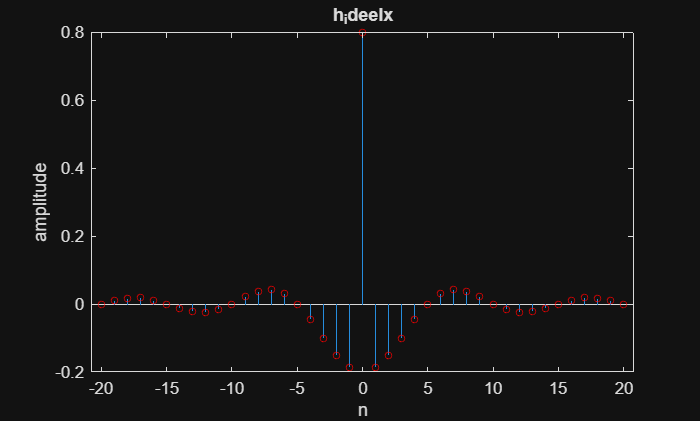

%definerer impulsresponset for et ideelt højpas
hi_HP = -(wc/pi)*sinc((n*wc)/pi); % for n ikke lig 0 

% her er betingelserne på n == 0 opfyldt også 
h_ideel = hi_HP;               % gælder for alle n
h_ideel(n==0) = 1 - wc/pi;     % KUN n = 0 rettes

%plotter med n vektor fra n=-20 til n=20 
stem(n,h_ideel,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
xlabel("n");
ylabel("amplitude")
title("h_ideelx")

%printer værdierne af impulsresponset for de angivede n værdier 
h0 = h_ideel(n==0)

h0 = 0.8000

h3 = h_ideel(n==3)

h3 = -0.1009

h6 = h_ideel(n==6)

h6 = 0.0312

h9 = h_ideel(n==9)

h9 = 0.0208

h12 = h_ideel(n==12)

h12 = -0.0252


clear
Fs = 2000; %sampling frekvens
Ts = 1/Fs; % sampling periode 
fc = 200/Fs; % norm cutoff
wc = fc*2*pi %norm angulær cutoff

wc = 0.6283

%n vektor til at iterere 
n = [-20:1:20]; 

Ntaps = 23; 

M = Ntaps -1 

M = 22

K = M/2

K = 11

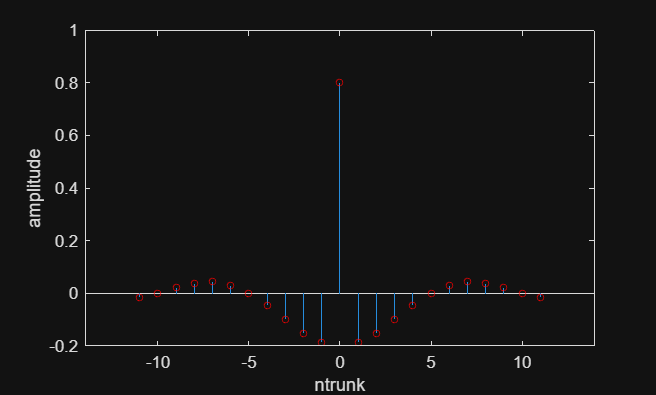

nHp = [-K:1:K];

hi_HP = -(wc/pi)*sinc((nHp*wc)/pi); % for n ikke lig    0 

% her er betingelserne på n == 0 opfyldt også 
h_ideel = hi_HP;               % gælder for alle n
h_ideel(nHp==0) = (pi - wc)/pi;     % KUN n = 0 rettes

%plotter med n vektor fra n=-20 til 20 
stem(nHp,h_ideel,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
xlabel("ntrunk");
ylabel("amplitude")
xlim([-14,14])
ylim([-0.2,1])

hold off

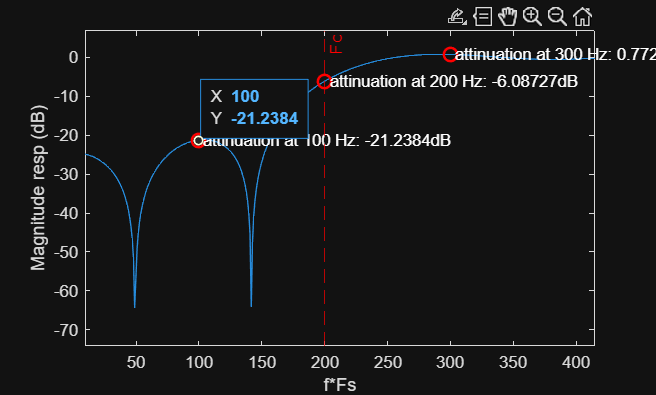


[H, freqdig] = freqz(h_ideel,1,1024,Fs);

plot(freqdig,20*log10(abs(H)))
xlabel("f*Fs");
ylabel("Magnitude resp (dB)")
xlim([0,400])
ylim([-80,10])
xline(fc*Fs,'--r', "Fc")
hold on
%frekvens
[~, idx100] = min(abs(freqdig - 100));
[~, idx200] = min(abs(freqdig - 200));
[~, idx300] = min(abs(freqdig - 300));
% Hent værdierne på frekvensresponsen
y100 = 20*log10(abs(H(idx100)));
y200=  20*log10(abs(H(idx200)));
y300 =  20*log10(abs(H(idx300)));
% Plot punkterne
plot(100, y100, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(200, y200, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(300, y300, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)

text(freqdig(idx100), y100, ' attinuation at 100 Hz: -21.2384dB ', 'Color','white', 'FontSize',10);
text(freqdig(idx200), y200, ' attinuation at 200 Hz: -6.08727dB', 'Color','white', 'FontSize',10);
text(freqdig(idx300), y300, ' attinuation at 300 Hz: 0.77297dB', 'Color','white', 'FontSize',10);
hold off 

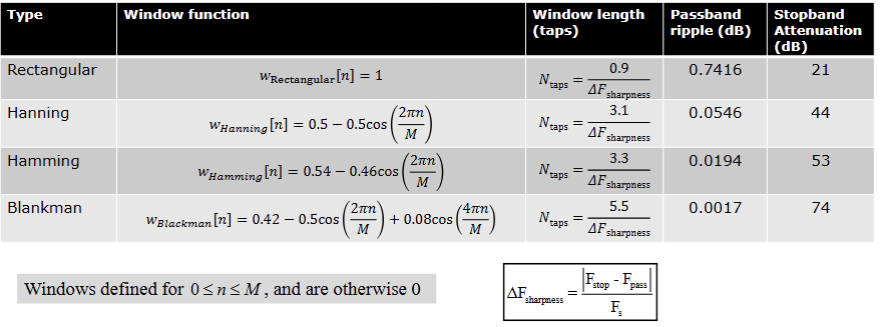

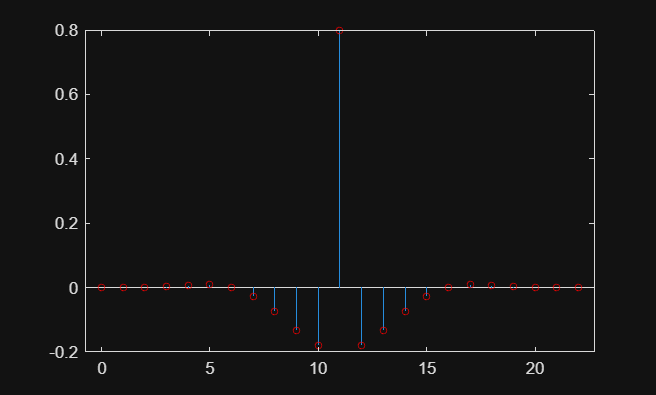

% vi kan tage window funktionen direkte fra tabellen og vi noterer os at vi
% allerede har alle værdier skrevet ind vi skal dog have en ny n vektor
% da den skal gå i de positive værdier SPØRG TIL GRUPPEREGNING
n_Black = [0:1:M];
w_Black = 0.42-0.5*cos((2*pi*n_Black)/M)+ 0.08*cos((4*pi*n_Black)/M);

h_w = h_ideel .* w_Black;

stem(n_Black,h_w,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')


% husk her at 12'e element er det h_w(11)
hw11 = h_w(12)

hw11 = 0.8000

hw14 = h_w(15)

hw14 = -0.0743

hw17 = h_w(18)

hw17 = 0.0085

hw20 = h_w(21) 

hw20 = 6.7784e-04

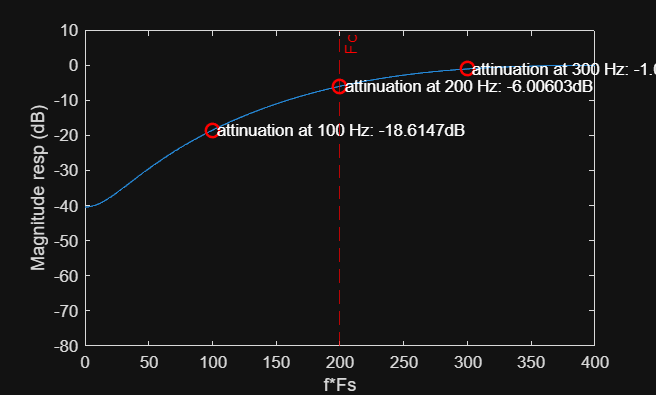



[H2, freqdig] = freqz(h_w,1,1024,Fs);

plot(freqdig,20*log10(abs(H2)))
xlabel("f*Fs");
ylabel("Magnitude resp (dB)")
xlim([0,400])
ylim([-80,10])
xline(fc*Fs,'--r', "Fc")
20*log10(abs(H2(100)));
20*log10(abs(H2(200)));
20*log10(abs(H2(300)));
hold on
%frekvens
[~, idx100] = min(abs(freqdig - 100));
[~, idx200] = min(abs(freqdig - 200));
[~, idx300] = min(abs(freqdig - 300));
% Henter værdierne på frekvensresponsen
y100 = 20*log10(abs(H2(idx100)));
y200=  20*log10(abs(H2(idx200)));
y300 =  20*log10(abs(H2(idx300)));
% Plotter punkterne
plot(100, y100, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(200, y200, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
plot(300, y300, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)

text(freqdig(idx100), y100, ' attinuation at 100 Hz: -18.6147dB ', 'Color','white', 'FontSize',10);
text(freqdig(idx200), y200, ' attinuation at 200 Hz: -6.00603dB', 'Color','white', 'FontSize',10);
text(freqdig(idx300), y300, ' attinuation at 300 Hz: -1.09679dB', 'Color','white', 'FontSize',10);
hold off 